# Lattice Modulation

## Set atom and magnetic field

% atom
atom = Alkali("Lithium7");

% B field
bList = num2cell(linspace(1.3e-2,1.4e-2,48));
niB = 543.6e-4; %non-interacting feshbach field
bField = cellfun(@(x) MagneticField(...
    bias = [0;0;niB],...
    gradient = [0,0,0;0,0,0;0,x,0]),bList,'UniformOutput',false);

## Set benchmark simulation

% set laser
laser = GaussianBeam( ...
    wavelength = 1064e-9,...
    direction = [0;1;0],...
    polarization = [0;0;1],...
    power = 0.6, ...
    waist = 110e-6 ...
    );
laser = {laser};

% set optical lattice
ol = OpticalLattice(atom,laser{1});

% initial condition
sigmaList = 2.5e-6;
% sigmaList = 1e-6:2e-6:12e-6;
[~,uk] = ol.computeBand1D(0,0);
uk = uk{1};
ic = InitialCondition("SeSim1D");
for ii = 1:numel(sigmaList)
    ic(ii) = InitialCondition("SeSim1D");
    ic(ii).WaveFunctionFunc = @(x) exp(-(x).^2 / 4 / sigmaList(ii)^2) .* uk(x);
end

% set modulation
nMod = 1;
modFreq = linspace(89,89,nMod) * 1e3;
modu = cell(1,nMod);
for ii = 1:nMod
    modu{ii} = Modulation(...
        depth = 0.05, ...
        duration = 9e-3, ...
        frequency = modFreq(ii), ...
        timing = 0);
end
% modu = {modu};

% simulation objects
% se = LatticeSeSim1D("Test", ...
%     laser = laser,...
%     magneticField = bField,...
%     modulation = modu,...
%     timeStep=1e-7,...
%     totalTime=9e-3,...
%     spaceRange = 400e-06,...
%     spaceStep = 5e-9,...
%     initialCondition = ic);
% se.start

se2 = LatticeSeSim1D("Test", ...
    laser = laser,...
    magneticField = bField,...
    latticeModulation = modu,...
    timeStep=1e-7,...
    totalTime=9e-3,...
    spaceRange = 400e-06,...
    spaceStep = 5e-8,...
    initialCondition = ic);

Constructing the object.
Setting up folders.
Creating a database entry.
Updating the object file.


se2.start

Updating the object file.
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.


## Plot

% plot benchmark
trialNumber = 22;
obj = loadTrial(createReader("simulation"),"lattice_schrodinger_equation_simulation_1d",trialNumber);
% obj.SimRun(1).showSpaceTime
nRun = numel(obj.SimRun);
freqList = zeros(1,nRun);
ampList = zeros(1,nRun);
for ii = 1:nRun
    rawData = obj.SimRun(ii).showPeak;
    fitData = SineFit1D(rawData);
    fitData.do;
    freqList(ii) = fitData.Coefficient(2);
    ampList(ii) = fitData.Coefficient(1);
end

## Analysis: animation

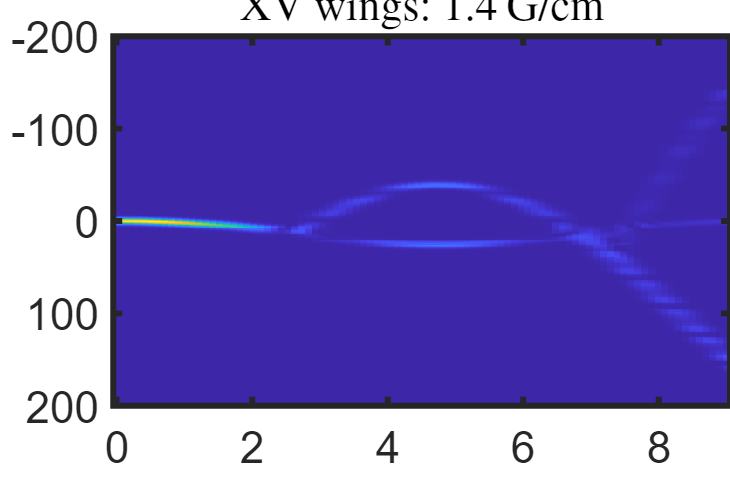

trialNumber = 38;
filename = "step50nm.gif";
startDelay=.5;
midDelay=.1;
endDelay=.5;
obj = loadTrial(createReader("simulation"),"lattice_schrodinger_equation_simulation_1d",trialNumber);
nSpace = obj.SimRun(1).NSpaceStep;
nRun = numel(obj.SimRun);
psiList = zeros(nRun,nSpace);
for ii = 1:nRun
    psiList(ii,:) = obj.SimRun(ii).readRun("FinalWaveFunction");
    obj.SimRun(ii).showSpaceTime;
    fig = gcf;
    imgAxes = gca;

    % Update title
    imgAxes.Title.String = "XV wings: $" + num2str(norm(bField{ii}.GradientLu)) + "~\mathrm{G/cm}$";
    imgAxes.Title.Interpreter = "latex";
    render

    % Save as gif
    frame = getframe(fig);
    im = frame2im(frame);
    [A,map] = rgb2ind(im,256);
    if ii == 1
        imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',startDelay);
    else
        if ii==nRun
            imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',endDelay);
        else
            imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',midDelay);
        end
    end
end

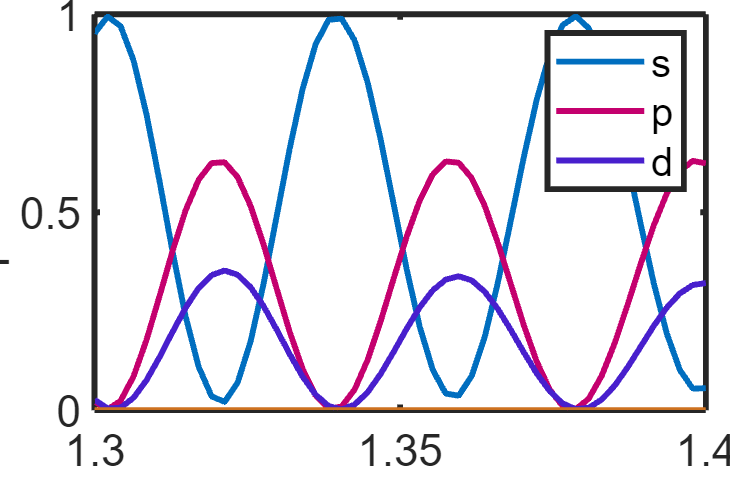


x = obj.SimRun(1).SpaceList;
bandPop = ol.computeBandPopulation1D(psiList,x,2);
bListGauss = cell2mat(bList) * 1e2;
figure
plot(bListGauss,bandPop)
xlabel("XV wings field gradient [Gauss/cm]")
ylabel("Population")
legend("s","p","d")
render
saveas(gcf,"step50nm","png")